# Create and Train a Deep Learning Model

Script for creating and training a deep learning network with the following properties:

Run this script to create the network layers, import training and validation data, and train the network. The network layers are stored in the workspace variable `layers`. The trained network is stored in the workspace variable `net`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 17-Nov-2021 21:57:12

## Load Training Setup Data

Load the data used to set up training. The training setup file contains the parameters for network initialization and the training and validation data. For transfer learning, the network initialization parameters are the parameters of the initial pretrained network.

trainingSetup = load("/mnt/H/КПИ/proga/ШИ/labs/lab9/params_FF_NN.mat");

## Import Data

Import training and validation data.

imdsTrain = trainingSetup.imdsTrain;
[imdsTrain, imdsValidation] = splitEachLabel(imdsTrain,0.7,"randomized");

% Resize the images to match the network input layer.
augimdsTrain = augmentedImageDatastore([28 28 1],imdsTrain);
augimdsValidation = augmentedImageDatastore([28 28 1],imdsValidation);

## Set Training Options

Specify options to use when training.

opts = trainingOptions("sgdm",...
    "ExecutionEnvironment","auto",...
    "InitialLearnRate",0.01,...
    "MaxEpochs",5,...
    "Shuffle","every-epoch",...
    "Plots","training-progress",...
    "ValidationData",augimdsValidation);

## Create Array of Layers

layers = [
    imageInputLayer([28 28 1],"Name","imageinput")
    convolution2dLayer([3 3],32,"Name","conv","Padding","same")
    batchNormalizationLayer("Name","batchnorm")
    reluLayer("Name","relu")
    fullyConnectedLayer(10,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

## Train Network

Train the network using the specified options and training data.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |       10.16% |       10.10% |       2.7676 |       5.1444 |          0.0100 |
|       1 |          50 |       00:00:10 |       70.31% |       74.43% |       0.9134 |       0.8383 |          0.0100 |
|       2 |         100 |       00:00:14 |       88.28% |       88.93% |       0.4128 |       0.4115 |          0.0100 |
|       3 |         150 |       00:00:18 |       92.19% |       93.57% |       0.2074 |   

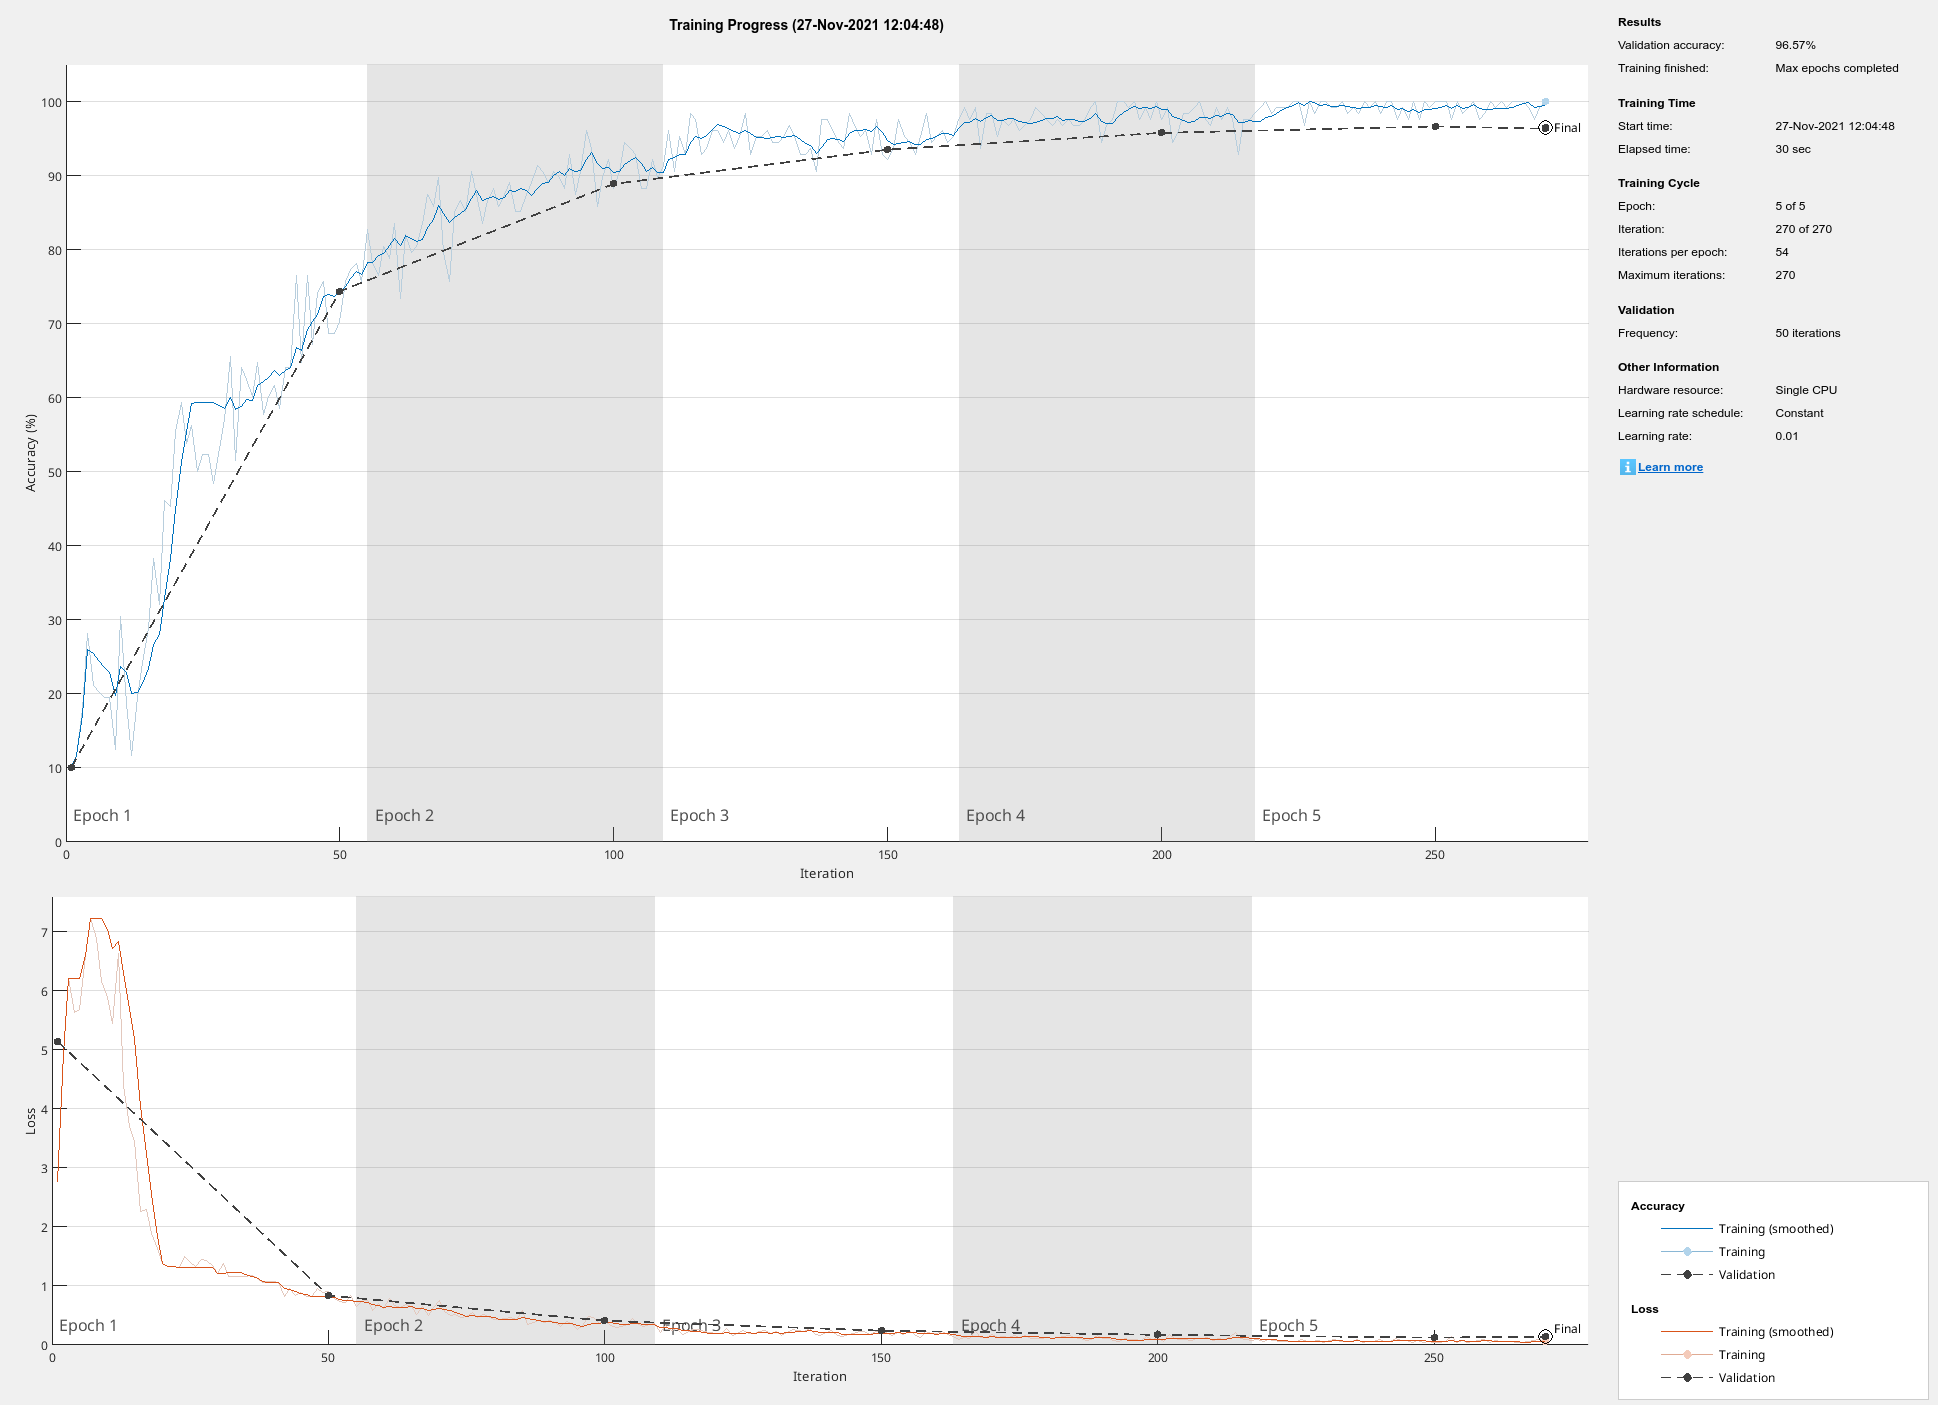

[net, traininfo] = trainNetwork(augimdsTrain,layers,opts);